%%<<<<<<<<<<<<<<<<<<< EIS data >>>>>>>>>>>>>>>>>>>>>
Freq_eis = eisdata(:, 1);
Real_bat_eis = eisdata(:, 2);
Imag_bat_eis = eisdata(:, 3);

% Calculate magnitude and phase
MAG_Z_eis = abs(Real_bat_eis + 1i * Imag_bat_eis);
Phase_Z_eis = angle(Real_bat_eis + 1i * Imag_bat_eis) * 180 / pi;

%%<<<<<<<<<<<<<<< simulation data >>>>>>>>>>>>>>>>>>>>

%%<<<<<<<<<<<<<<< 2500 >>>>>>>>>>>>>>
%setup for FFT
L_sim2500=round(T_sim_2500/Ts_2500)-1;
Fs_2500=1/Ts_2500;
f_b_2500=f_clk_2500/L_MLBS;

%FFT for cell voltage & current
FFT_v_sim2500 = fft(out_2500.V_bat.Data, L_sim2500);
FFT_i_sim2500 = fft(-out_2500.I_bat.Data, L_sim2500);

% Initialize arrays to store results
Freq_sim2500 = zeros(1, 204);
MAG_Z_sim2500 = zeros(1, 204);
Phase_Z_sim2500 = zeros(1, 204);
Real_bat_sim2500 = zeros(1, 204);
Imag_bat_sim2500 = zeros(1, 204);

% Loop through the calculations with k from 1 to 25, step 1
k_values_sim2500 = 1:204;
for idx = 1:length(k_values_sim2500)
    k_sim2500 = k_values_sim2500(idx);
    N_k_sim2500 = round(f_b_2500 * k_sim2500 * L_sim2500 / Fs_2500 + 1);
    Freq_sim2500(idx) = (N_k_sim2500 - 1) * Fs_2500 / L_sim2500;

    V_k_sim2500 = FFT_v_sim2500(N_k_sim2500);
    I_k_sim2500 = FFT_i_sim2500(N_k_sim2500);

    MagV_k_sim2500 = 2 * abs(V_k_sim2500) / L_sim2500;
    PhaseV_k_sim2500 = angle(V_k_sim2500) * 180 / pi;

    MagI_k_sim2500 = 2 * abs(I_k_sim2500) / L_sim2500;
    PhaseI_k_sim2500 = angle(I_k_sim2500) * 180 / pi;

    Z_k_sim2500 = V_k_sim2500 / I_k_sim2500;
    MAG_Z_sim2500(idx) = abs(Z_k_sim2500);
    Phase_Z_sim2500(idx) = angle(Z_k_sim2500)*180/pi;
    Real_bat_sim2500(idx) = real(Z_k_sim2500);
    Imag_bat_sim2500(idx) = imag(Z_k_sim2500);
end


%%<<<<<<<<<<<<<<< 20 >>>>>>>>>>>>>>
%setup for FFT
L_sim20=round(T_sim_20/Ts_20)-1;
Fs_20=1/Ts_20;
f_b_20=f_clk_20/L_MLBS;


%FFT for cell voltage & current
FFT_v_sim20 = fft(out_20.V_bat.Data, L_sim20);
FFT_i_sim20 = fft(-out_20.I_bat.Data, L_sim20);

% Initialize arrays to store results
Freq_sim20 = zeros(1, 204);
MAG_Z_sim20 = zeros(1, 204);
Phase_Z_sim20 = zeros(1, 204);
Real_bat_sim20 = zeros(1, 204);
Imag_bat_sim20 = zeros(1, 204);

% Loop 
k_values_sim20 = 1:204;
for idx = 1:length(k_values_sim20)
    k_sim20 = k_values_sim20(idx);
    N_k_sim20 = round(f_b_20 * k_sim20 * L_sim20 / Fs_20 + 1);
    Freq_sim20(idx) = (N_k_sim20 - 1) * Fs_20 / L_sim20;

    V_k_sim20 = FFT_v_sim20(N_k_sim20);
    I_k_sim20 = FFT_i_sim20(N_k_sim20);

    MagV_k_sim20 = 2 * abs(V_k_sim20) / L_sim20;
    PhaseV_k_sim20 = angle(V_k_sim20) * 180 / pi;

    MagI_k_sim20 = 2 * abs(I_k_sim20) / L_sim20;
    PhaseI_k_sim20 = angle(I_k_sim20) * 180 / pi;

    Z_k_sim20 = V_k_sim20 / I_k_sim20;
    MAG_Z_sim20(idx) = abs(Z_k_sim20);
    Phase_Z_sim20(idx) = angle(Z_k_sim20)*180/pi;
    Real_bat_sim20(idx) = real(Z_k_sim20);
    Imag_bat_sim20(idx) = imag(Z_k_sim20);
end


%%<<<<<<<<<<<<<<< 5 >>>>>>>>>>>>>>
%setup for FFT
L_sim5=round(T_sim_5/Ts_5)-1;
Fs_5=1/Ts_5;
f_b_5=f_clk_5/L_MLBS;

%FFT for cell voltage & current
FFT_v_sim5 = fft(out_5.V_bat.Data, L_sim5);
FFT_i_sim5 = fft(-out_5.I_bat.Data, L_sim5);

% Initialize arrays to store results
Freq_sim5 = zeros(1, 204);
MAG_Z_sim5 = zeros(1, 204);
Phase_Z_sim5 = zeros(1, 204);
Real_bat_sim5 = zeros(1, 204);
Imag_bat_sim5 = zeros(1, 204);

% Loop
k_values_sim5 = 1:204;
for idx = 1:length(k_values_sim5)
    k_sim5 = k_values_sim5(idx);
    N_k_sim5 = round(f_b_5 * k_sim5 * L_sim5 / Fs_5 + 1);
    Freq_sim5(idx) = (N_k_sim5 - 1) * Fs_5 / L_sim5;

    V_k_sim5 = FFT_v_sim5(N_k_sim5);
    I_k_sim5 = FFT_i_sim5(N_k_sim5);

    MagV_k_sim5 = 2 * abs(V_k_sim5) / L_sim5;
    PhaseV_k_sim5 = angle(V_k_sim5) * 180 / pi;

    MagI_k_sim5 = 2 * abs(I_k_sim5) / L_sim5;
    PhaseI_k_sim5 = angle(I_k_sim5) * 180 / pi;

    Z_k_sim5 = V_k_sim5 / I_k_sim5;
    MAG_Z_sim5(idx) = abs(Z_k_sim5);
    Phase_Z_sim5(idx) = angle(Z_k_sim5)*180/pi;
    Real_bat_sim5(idx) = real(Z_k_sim5);
    Imag_bat_sim5(idx) = imag(Z_k_sim5);
end


% simulation data
Real_bat_sim = [Real_bat_sim2500, Real_bat_sim20, Real_bat_sim5];
Imag_bat_sim = [Imag_bat_sim2500, Imag_bat_sim20, Imag_bat_sim5];
MAG_Z_sim = [MAG_Z_sim5, MAG_Z_sim20, MAG_Z_sim2500];
Phase_Z_sim = [Phase_Z_sim5, Phase_Z_sim20, Phase_Z_sim2500];
Freq_sim = [Freq_sim5, Freq_sim20, Freq_sim2500];



%%<<<<<<<<<<<<<<<<<< PRBS data >>>>>>>>>>>>>>>>>>>>>>>
%experiment data
current_I_2500 = -TWOo9bitI2500(:, 2);
voltage_V_2500 = TWOo9bitV2500(:, 2);

current_I_20 = -TWOo9bitI20(:, 2);
voltage = TWOo9bitV20(:, 2);
%for low clock frequency 
voltage_V_20 = detrend(voltage);

current_I_5 = -TWOo9bitI5(:, 2);
voltage_V = TWOo9bitV5(:, 2);
%for low clock frequency 
voltage_V_5 = detrend(voltage_V);


%setup for FFT
L_PRBS_2500 = length(current_I_2500); 
L_PRBS_20 = length(current_I_20); 
L_PRBS_5 = length(current_I_5); 
N = 9;
L_mlbs = 2^N - 1;


%%<<<<<<<<<<<<<< clock frequency = 2500Hz >>>>>>>>>>>>>>>>>

F_clk_2500 = 2500;
F_b_2500=F_clk_2500/L_mlbs

F_b_2500 = 4.8924

T_S_2500 = 4e-06;%main scale = 100ms
F_S_2500=1/T_S_2500;
F_2500=F_S_2500*(0:(L_PRBS_2500/2))/L_PRBS_2500;
 

%FFT for cell voltage & current when f_clk=2500Hz
FFT_v_2500 = fft(voltage_V_2500, L_PRBS_2500);
FFT_i_2500 = fft(current_I_2500, L_PRBS_2500);

% Initialize arrays to store results
Freq_2500 = zeros(1, 204);
MAG_Z_2500 = zeros(1, 204);
Phase_Z_2500 = zeros(1, 204);
Real_bat_2500 = zeros(1, 204);
Imag_bat_2500 = zeros(1, 204);

% Loop to cover range of 4.89Hz-1000Hz
k_values_2500 = 1:204;
for idx = 1:length(k_values_2500)
    k_2500 = k_values_2500(idx);
    N_k_2500 = round(F_b_2500 * k_2500 * L_PRBS_2500 / F_S_2500 + 1);
    Freq_2500(idx) = (N_k_2500 - 1) * F_S_2500 / L_PRBS_2500;

    V_k_2500 = FFT_v_2500(N_k_2500);
    I_k_2500 = FFT_i_2500(N_k_2500);

    MagV_k_2500 = 2 * abs(V_k_2500) / L_PRBS_2500;
    PhaseV_k_2500 = angle(V_k_2500) * 180 / pi;

    MagI_k_2500 = 2 * abs(I_k_2500) / L_PRBS_2500;
    PhaseI_k_2500 = angle(I_k_2500) * 180 / pi;

    Z_k_2500 = V_k_2500 / I_k_2500;
    MAG_Z_2500(idx) = abs(Z_k_2500);
    Phase_Z_2500(idx) = angle(Z_k_2500)*180/pi;
    Real_bat_2500(idx) = real(Z_k_2500);
    Imag_bat_2500(idx) = imag(Z_k_2500);
end

%<<<<<<<<<<<<<< clock frequency = 20Hz >>>>>>>>>>>>>>>>>>>

F_clk_20 = 20; 
F_b_20=F_clk_20/L_mlbs

F_b_20 = 0.0391

T_S_20 = 4e-04; %main sclae = 10s
F_S_20=1/T_S_20;

%FFT for cell voltage & current when f_clk=20Hz
FFT_v_20 = fft(voltage_V_20, L_PRBS_20);
FFT_i_20 = fft(current_I_20, L_PRBS_20);

% Initialize arrays to store results
Freq_20 = zeros(1, 204);
MAG_Z_20 = zeros(1, 204);
Phase_Z_20 = zeros(1, 204);
Real_bat_20 = zeros(1, 204);
Imag_bat_20 = zeros(1, 204);

% Loop to cover range of 0.039Hz-5Hz
k_values_20 = 1:204;
for idx = 1:length(k_values_20)
    k_20 = k_values_20(idx);
    N_k_20 = round(F_b_20 * k_20 * L_PRBS_20 / F_S_20 + 1);
    Freq_20(idx) = (N_k_20 - 1) * F_S_20 / L_PRBS_20;

    V_k_20 = FFT_v_20(N_k_20);
    I_k_20 = FFT_i_20(N_k_20);

    MagV_k_20 = 2 * abs(V_k_20) / L_PRBS_20;
    PhaseV_k_20 = angle(V_k_20) * 180 / pi;

    MagI_k_20 = 2 * abs(I_k_20) / L_PRBS_20;
    PhaseI_k_20 = angle(I_k_20) * 180 / pi;

    Z_k_20 = V_k_20 / I_k_20;
    MAG_Z_20(idx) = abs(Z_k_20);
    Phase_Z_20(idx) = angle(Z_k_20)*180/pi;
    Real_bat_20(idx) = real(Z_k_20);
    Imag_bat_20(idx) = imag(Z_k_20);
end

%<<<<<<<<< clock frequency = 5Hz >>>>>>>>>>>>>>>

F_clk_5 = 5; 
F_b_5=F_clk_5/L_mlbs

F_b_5 = 0.0098

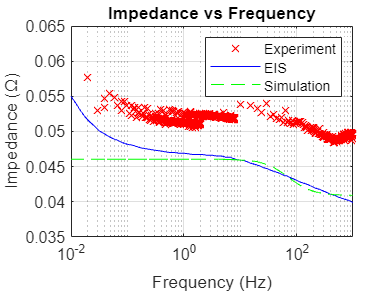

T_S_5 = 2e-03;%main scale = 50s
F_S_5=1/T_S_5;

%FFT for cell voltage & current when f_clk=5Hz
FFT_v_5 = fft(voltage_V_5, L_PRBS_5);
FFT_i_5 = fft(current_I_5, L_PRBS_5);

% Initialize arrays to store results
Freq_5 = zeros(1, 204);
MAG_Z_5 = zeros(1, 204);
Phase_Z_5 = zeros(1, 204);
Real_bat_5 = zeros(1, 204);
Imag_bat_5 = zeros(1, 204);

% Loop to cover range of 0.01Hz-0.04Hz
k_values_5 = 1:204;
for idx = 1:length(k_values_5)
    k_5 = k_values_5(idx);
    N_k_5 = round(F_b_5 * k_5 * L_PRBS_5 / F_S_5 + 1);
    Freq_5(idx) = (N_k_5 - 1) * F_S_5 / L_PRBS_5;

    V_k_5 = FFT_v_5(N_k_5);
    I_k_5 = FFT_i_5(N_k_5);

    MagV_k_5 = 2 * abs(V_k_5) / L_PRBS_5;
    PhaseV_k_5 = angle(V_k_5) * 180 / pi;

    MagI_k_5 = 2 * abs(I_k_5) / L_PRBS_5;
    PhaseI_k_5 = angle(I_k_5) * 180 / pi;

    Z_k_5 = V_k_5 / I_k_5;
    MAG_Z_5(idx) = abs(Z_k_5);
    Phase_Z_5(idx) = angle(Z_k_5)*180/pi;
    Real_bat_5(idx) = real(Z_k_5);
    Imag_bat_5(idx) = imag(Z_k_5);
end


%% experiment data 
Real_bat = [Real_bat_2500, Real_bat_20, Real_bat_5];
Imag_bat = [Imag_bat_2500, Imag_bat_20, Imag_bat_5];
MAG_Z = [MAG_Z_5, MAG_Z_20, MAG_Z_2500];
Phase_Z = [Phase_Z_5, Phase_Z_20, Phase_Z_2500];
Freq = [Freq_5, Freq_20, Freq_2500];


%%<<<<<<<<<<<<<<<< plots >>>>>>>>>>>>>>>>>>>>>>>

%impedence vs frequency plot
figure(1);

semilogx(Freq, MAG_Z, 'rx');
hold on;
semilogx(Freq_eis, MAG_Z_eis, 'b-');
hold on;
semilogx(Freq_sim, MAG_Z_sim, 'g--');

title('Impedance vs Frequency');
xlabel("Frequency (Hz)");
ylabel("Impedance (Ω)");
xlim([0.01,1000]);
ylim([0.035,0.065]);
legend('Experiment','EIS','Simulation');
grid on;
hold off;

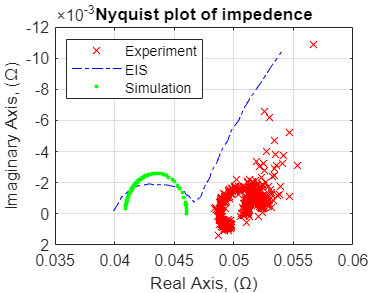



% Bode plot of magnitude and phase
% figure(2);
% 
% subplot(2, 1, 1);
% semilogx(Freq, 20*log10(MAG_Z), 'rx', 'DisplayName', 'Experiment');
% hold on;
% semilogx(Freq_eis, 20*log10(MAG_Z_eis), 'b-', 'DisplayName', 'EIS');
% hold on;
% semilogx(Freq_sim, 20*log10(MAG_Z_sim), 'g--', 'DisplayName', 'Simulation');
% hold off;
% title('Bode Plot of Impedance - Magnitude');
% xlim([0.01,1000]);
% ylim([-28, -23]);
% xlabel('Frequency (Hz)');
% ylabel('Magnitude (dB)');
% legend show;
% grid on;
% 
% subplot(2, 1, 2);
% semilogx(Freq, Phase_Z, 'rx', 'DisplayName', 'Experiment');
% hold on;
% semilogx(Freq_eis, Phase_Z_eis, 'b-', 'DisplayName', 'EIS');
% hold on;
% semilogx(Freq_sim, Phase_Z_sim, 'g--', 'DisplayName', 'Simulation');
% hold off;
% title('Bode Plot of Impedance - Phase');
% xlim([0.01,1000]);
% ylim([-10, 5]);
% xlabel('Frequency (Hz)');
% ylabel('Phase (degrees)');
% legend('Location','southeast');
% legend show;
% grid on;



%Nyquist plot based on battery ECM parameters

figure(3);
plot(Real_bat, Imag_bat, 'rx');
hold on;
plot(Real_bat_eis, Imag_bat_eis, 'b-.');
hold on;
plot(Real_bat_sim, Imag_bat_sim, 'g.');
title('Nyquist plot of impedence');
xlabel("Real Axis, (Ω)");
ylabel("Imaginary Axis, (Ω)");
set(gca, 'XTick',0.035:0.005:0.06);
set(gca,'ydir','reverse');
xlim([0.035,0.06]);
ylim([-12e-3,2e-3]);
legend('Location','northwest');
legend('Experiment','EIS','Simulation');
grid on;
hold off;